# Analysis

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Three_Pipes_height_50um
r_sensor=2 mm
Q_inlet_CNN=5 uL/min
height_pipe=50 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s


time_delta = 0.5000

ans = 20

ans = 19.5000

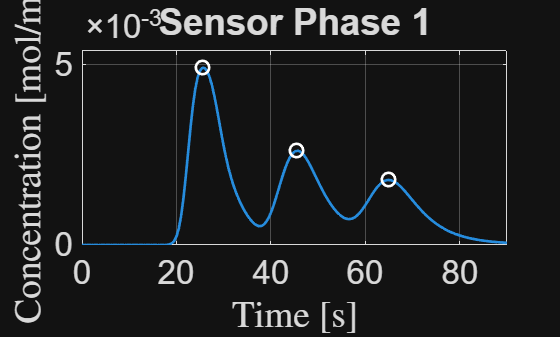

Distance between peaks


ans = 8.5000

ans = 17

Relative error between peaks 1 and 2


ans = 99.9947

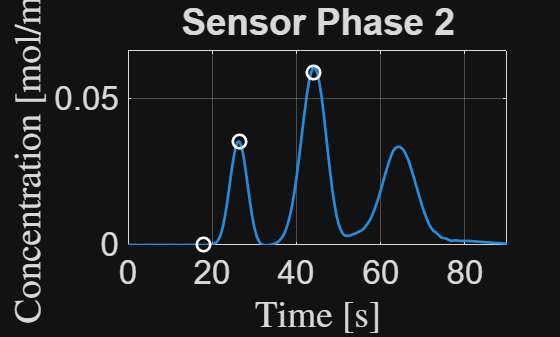

Analysis_Phase_2

#### Phase 3: Load

% Specify the CSV file
csvFileName = 'c_CNN_Phase_3.csv';
% Var 2- > alpha_outlet=0.65; height_pipe=35um
% Var 3- > alpha_outlet=0.7; height_pipe=35um
% Var 4- > alpha_outlet=0.65; height_pipe=25um
% Var 5- > alpha_outlet=0.63; height_pipe=25um, alpha_w=0.64, alpha_molecules=0.35
% Var 6- >alpha_outlet=0.63; height_pipe=25um, alpha_w=0.7, alpha_molecules=0.35
% Var 7- >alpha_outlet=0.63; height_pipe=25um, alpha_w=0.75, alpha_molecules=0.45
% Var 8- >alpha_outlet=0.63; height_pipe=25um, alpha_w=0.8, alpha_molecules=0.5
% Var 9- >alpha_outlet=0.63; height_pipe=25um, alpha_w=0.8, alpha_molecules=0.8
% Var 10- >alpha_outlet=0.6; height_pipe=25um, alpha_w=0.9, alpha_molecules=0.8
% Var 11- >alpha_outlet=0.5; height_pipe=25um, alpha_w=0.9, alpha_molecules=0.8
% Var 12- >alpha_outlet=0.5; height_pipe=25um, alpha_w=0.9, alpha_molecules=0.8
% Var 13- >alpha_outlet=0.55; height_pipe=25um, alpha_w=0.9, alpha_molecules=0.8
% Var 14- >alpha_outlet=0.45; height_pipe=25um, alpha_w=0.9, alpha_molecules=0.8
% Var 15- >alpha_outlet=0.5; height_pipe=25um, alpha_w=0.9, alpha_molecules=0.8
% Var 16- >alpha_outlet=0.7; height_pipe=25um, alpha_w=0.9, alpha_molecules=0.8
% Var 17- >alpha_outlet=0.6; height_pipe=25um, alpha_w=0.9, alpha_molecules=0.8
% Var 18- >alpha_outlet=0.58; height_pipe=25um, alpha_w=0.9, alpha_molecules=0.8

%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% Var 2 -> height of 35um
% Var 3 -> height of 25um
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_CNN=readtable(csvFileName,opts);
t_COMSOL_Phase_3=(Table_c_Pipe_CNN.Var1);
dt=t_COMSOL_Phase_3(2)-t_COMSOL_Phase_3(1);
c_COMSOL_CNN_Phase_3=(Table_c_Pipe_CNN.Var2);
h_COMSOL_CNN_Phase_3=gradient(c_COMSOL_CNN_Phase_3,t_COMSOL_Phase_3);

%finding the peaks
%First peak
x1=1;
x2=x1+round(1/5*length(h_COMSOL_CNN_Phase_3));
[~,t_peak_A_COMSOL_Phase_3]=max(h_COMSOL_CNN_Phase_3(x1:x2));

%Second peak
x1=x2;
x2=x1+(tau_sample)/dt;
[~,t_peak_B_COMSOL_Phase_3]=max(h_COMSOL_CNN_Phase_3(x1:x2));
t_peak_B_COMSOL_Phase_3=t_peak_B_COMSOL_Phase_3+x1-1;

%Third peak
x1=x2;
[~,t_peak_C_COMSOL_Phase_3]=max(h_COMSOL_CNN_Phase_3(x1:end));
t_peak_C_COMSOL_Phase_3=t_peak_C_COMSOL_Phase_3+x1-2;
% t_peak_C_COMSOL=(t_peak_C_COMSOL-1)*time_delta+(x1-1)*time_delta;

disp(['Sampling time'])

Sampling time


(t_peak_B_COMSOL_Phase_3-1)*dt-(t_peak_A_COMSOL_Phase_3-1)*dt

ans = 9

disp(['Sampling time'])

Sampling time


(t_peak_C_COMSOL_Phase_3-1)*dt-(t_peak_B_COMSOL_Phase_3-1)*dt

ans = 19.5000


disp(['Amplitude Peak 1'])

Amplitude Peak 1


h_COMSOL_CNN_Phase_3((t_peak_A_COMSOL_Phase_3))

ans = 4.1027e-05

disp(['Amplitude Peak 2'])

Amplitude Peak 2


h_COMSOL_CNN_Phase_3((t_peak_B_COMSOL_Phase_3))

ans = 0.0280

disp(['Amplitude Peak 3'])

Amplitude Peak 3


h_COMSOL_CNN_Phase_3((t_peak_C_COMSOL_Phase_3))

ans = 0.0294


disp(['Distance between peaks'])

Distance between peaks


(t_peak_B_COMSOL_Phase_2-t_peak_A_COMSOL_Phase_2)*time_delta

ans = 8.5000

(t_peak_C_COMSOL_Phase_2-t_peak_B_COMSOL_Phase_2)*time_delta

ans = 17


disp(['Relative error between peaks 1 and 2'])

Relative error between peaks 1 and 2


abs(h_COMSOL_CNN_Phase_2(t_peak_A_COMSOL_Phase_2)-h_COMSOL_CNN_Phase_2(t_peak_C_COMSOL_Phase_2))/h_COMSOL_CNN_Phase_2((t_peak_C_COMSOL_Phase_2))*100

ans = 99.9947

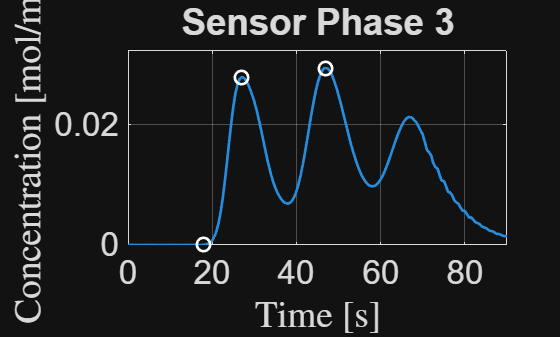



figure;

% % plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(t_COMSOL_Phase_3,h_COMSOL_CNN_Phase_3,'LineWidth',2); grid on; hold on;
plot((t_peak_A_COMSOL_Phase_3-1)*dt,h_COMSOL_CNN_Phase_3((t_peak_A_COMSOL_Phase_3)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
plot((t_peak_B_COMSOL_Phase_3-1)*dt,h_COMSOL_CNN_Phase_3((t_peak_B_COMSOL_Phase_3)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
plot((t_peak_C_COMSOL_Phase_3)*dt,h_COMSOL_CNN_Phase_3((t_peak_C_COMSOL_Phase_3)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;% plot([x1 x1]*time_delta,[0 1])
% plot([x1 x1]*time_delta,[0 1])
% plot([x2 x2]*time_delta,[0 1])

xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
title('Sensor Phase 3')
axis([0 t(end) 0 1.1*max(h_COMSOL_CNN_Phase_3)]);